# Analysis of Covid-19 WHO data

opts = weboptions;
opts.ContentType = 'table';
by_date = webread("https://opendata.ecdc.europa.eu/covid19/casedistribution/csv",opts);
by_date.Properties.VariableNames = ["date", "day", "month", "year", "cases", "deaths", "location", "geo_id", "code", "population"];

Preview 10 random rows

by_date(randi(height(by_date),1,10), :)

ans = 10×10 table
       date       day    month    year    cases    deaths               location                geo_id     code      population
    __________    ___    _____    ____    _____    ______    _______________________________    ______    _______    __________

    05/03/2020     5       3      2020       2        0      {'Belarus'                    }    {'BY'}    {'BLR'}    9.4854e+06
    21/01/2020    21       1      2020       0        0      {'Ecuador'                    }    {'EC'}    {'ECU'}    1.7084e+07
    15/01/2020    15       1      2020       0        0      {'Lebanon'                    }    {'LB'}    {'LBN'}    6.8489e+06
 

latestDate = max(by_date.date)

latestDate = datetime
   05/04/2020


## Group by country 

[G,ID] = findgroups( by_date.location);
ID = categorical(ID);
by_country = table;
by_country.name = ID;
by_country.geo_id = splitapply( @unique, by_date.geo_id, G );
by_country.population = splitapply( @max, by_date.population, G );

for ii = 1:height(by_country)
    try
        data = getCountryData(by_country.geo_id{ii});
        by_country.data(ii) = data;
    end
end


### Calculate Totals

warning off;
for n = 1:numel(ID)
    ix = find(G == n);
    by_date{ix,'total_deaths'}  = cumsum( by_date{ix,'deaths'}, 'reverse' );
    by_date{ix,'total_cases'}   = cumsum( by_date{ix,'cases'}, 'reverse' );
end
warning on;
by_country.total_deaths = splitapply( @max, by_date.total_deaths, G );
by_country.total_cases = splitapply( @max, by_date.total_cases, G );
by_country.latest_results = splitapply( @max, by_date.date, G );

### Find date of Nth death

N = 50;
by_country.date_deaths_N = splitapply( @(t,dt) findExeedanceDate(t,dt,N), by_date.date, by_date.total_deaths , G );

### Summary Statistics

maxDeaths = max(by_country.total_deaths);
maxCases = max(by_country.total_cases);
by_country = sortrows(by_country,'total_deaths','descend');

#### 10 Worse Impacted Countries by Total Deaths

by_country(1:10,:)

ans = 10×8 table
              name              geo_id    population        data        total_deaths    total_cases    latest_results    date_deaths_N
    ________________________    ______    __________    ____________    ____________    ___________    ______________    _____________

    Italy                       {'IT'}    6.0431e+07    [1×1 struct]       15362        1.2463e+05       05/04/2020       03-Mar-2020 
    Spain                       {'ES'}    4.6724e+07    [1×1 struct]       11744        1.2474e+05       05/04/2020       13-Mar-2020 
    United_States_of_America    {'US'}    3.2717e+08    [1×1 struct]        8501        3.1224e+05       05/04/2020       15-Mar-2020 
    France                      {'F

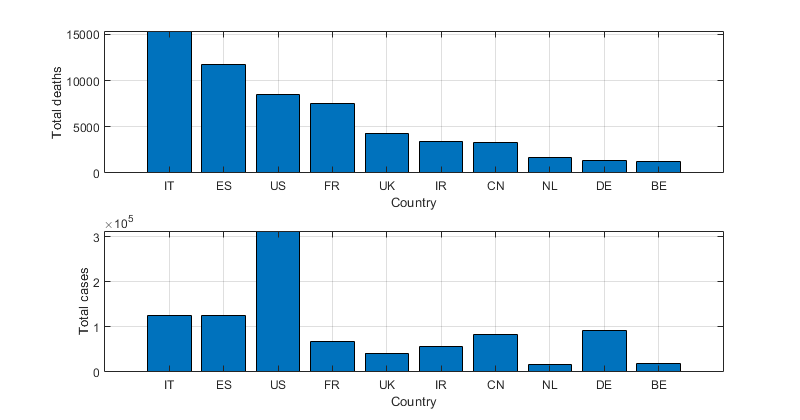

fig = figure;
fig.Position(3) = 800;
ax = subplot(2,1,1);
bar(ax,by_country{1:10,"total_deaths"})
ax.XTickLabel = by_country{1:10,"geo_id"};
xlabel('Country'); ylabel('Total deaths'); grid on;
ax = subplot(2,1,2);
bar(ax,by_country{1:10,"total_cases"})
ax.XTickLabel = by_country{1:10,"geo_id"};
xlabel('Country'); ylabel('Total cases'); grid on;

### View Geographical Distribution

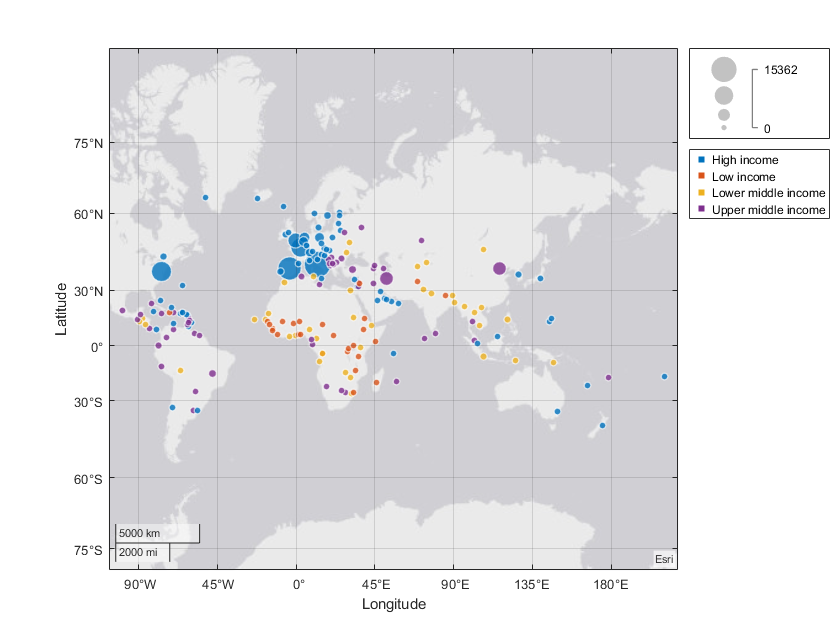

lat = {by_country.data.latitude}';
lon = {by_country.data.longitude}';
ix = ~cellfun(@isempty,lat );
lat = cellfun( @str2num, lat(ix) );
lon = cellfun( @str2num, lon(ix) );
total_deaths = by_country.total_deaths(ix);
incomeLevel = [by_country.data(ix).incomeLevel];
incomeLevel = {incomeLevel.value};

fig = figure;
fig.Position([3,4]) = [840,640];
geobubble(lat,lon,total_deaths,categorical(incomeLevel))

### Select countries to highlight

highlight = {'China' 'Italy' 'United_States_of_America' 'United_Kingdom' 'Spain' 'South_Korea'}'

highlight = 6×1 cell array
    {'China'                   }
    {'Italy'                   }
    {'United_States_of_America'}
    {'United_Kingdom'          }
    {'Spain'                   }
    {'South_Korea'             }


### Plot Total Death Count by Date

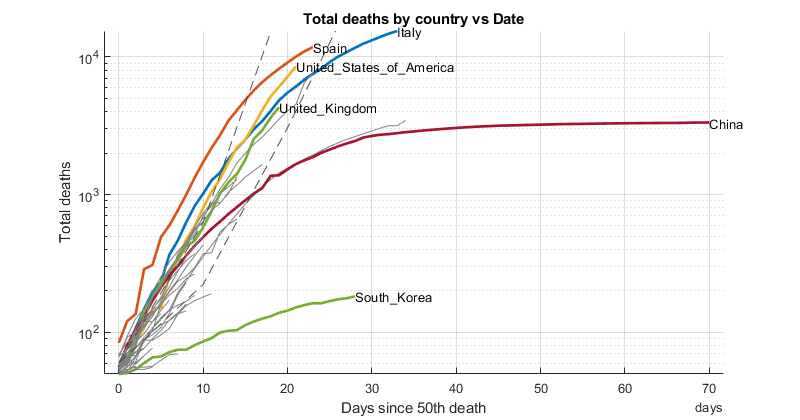

fig1 = figure;
fig1.Position(3) = 800;
ax1 = axes("NextPlot","add","YScale","log");
grid on
xlabel(ax1,"Days since " + num2str(N) + "th death")
ylabel(ax1,'Total deaths')
title( "Total deaths by country vs Date" )

for id = by_country.name'
    % Get single country summary
    country = by_country(by_country.name == id,:);
    
    % Index relevant data from main table
    ix = by_date.location == id & by_date.date >= country.date_deaths_N;
    
    % Skip country if no relevant rows
    if ~any(ix); continue; end
    
    % Calculate relative dates
    dt = by_date.date(ix) - country.date_deaths_N;
    total_deaths = by_date.total_deaths(ix);
    
    % Plot rate of deaths
    y = total_deaths;
    if any(id == highlight)
        semilogy(ax1, dt, y, 'LineWidth', 2)
        text(ax1, max(dt), max(y), strrep(char(id), '_', '\_'))
    else
        semilogy(ax1, dt, y, 'Color', [0.5 0.5 0.5])
    end
end
% Get time base
X = ax1.XTick;
xtickformat(ax1,'d')

ax1.YLimMode = 'manual';
c = [0.3 0.3 0.3];

% Apply 33% growth line
Y = 10*(1.33).^days(X) + N;
semilogy(ax1, X, Y,'--','Color',c)

% Apply 50% growth line
Y = 10*(1.50).^days(X) + N;
semilogy(ax1, X, Y,'--','Color',c)

### Plot Death Rate as Moving Average

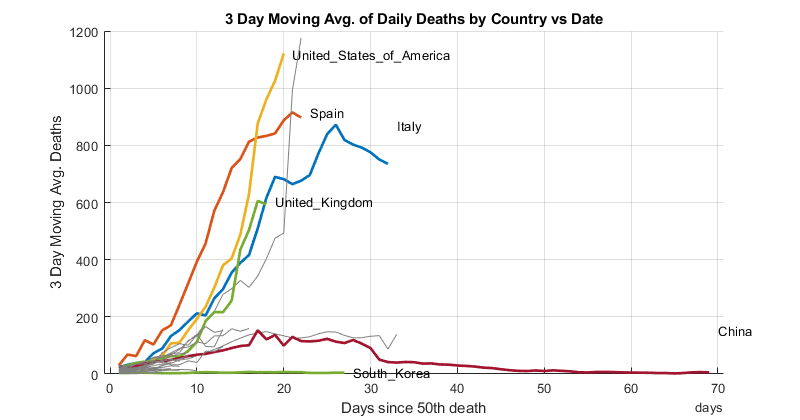

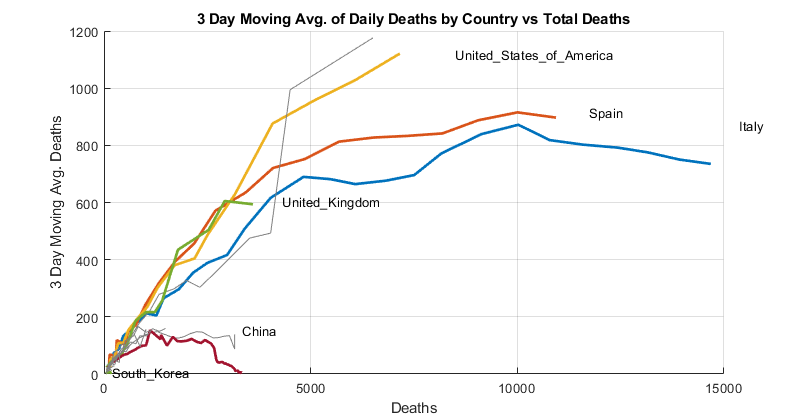

fig2 = figure;
fig2.Position(3) = 800;
ax2 = axes("NextPlot","add");
grid on
xlabel(ax2,"Days since " + num2str(N) + "th death")
ylabel(ax2,'3 Day Moving Avg. Deaths')
title( "3 Day Moving Avg. of Daily Deaths by Country vs Date" )

fig3 = figure;
fig3.Position(3) = 800;
ax3 = axes("NextPlot","add");
grid on
xlabel(ax3,"Deaths")
ylabel(ax3,'3 Day Moving Avg. Deaths')
title( "3 Day Moving Avg. of Daily Deaths by Country vs Total Deaths" )

for id = by_country.name'
    % Get single country summary
    country = by_country(by_country.name == id,:);
    
    % Index relevant data from main table
    ix = by_date.location == id & by_date.date >= country.date_deaths_N;
    
    % Skip country if no relevant rows
    if ~any(ix); continue; end
    
    % Calculate relative dates
    dt = by_date.date(ix) - country.date_deaths_N;
    total_deaths = by_date.total_deaths(ix);
    mov_avg_deaths = movmean( by_date{ix,'deaths'}, 3, 'Endpoints', 'fill' );
    
    % Plot moving average
    y = mov_avg_deaths;
    if any(id == highlight)
        plot(ax2, dt, y, 'LineWidth', 2)
        text(ax2, max(dt), max(y), strrep(char(id), '_', '\_'))
        xtickformat(ax2,'d')
    else
        plot(ax2, dt, y, 'Color', [0.5 0.5 0.5])
    end
    
    % Plot moving average vs deaths
    x = total_deaths;
    y = mov_avg_deaths;
    if any(id == highlight)
        plot(ax3, x, y, 'LineWidth', 2)
        text(ax3, max(x), max(y), strrep(char(id), '_', '\_'))
    else
        plot(ax3, x, y, 'Color', [0.5 0.5 0.5])
    end
end

### View all countries distribution

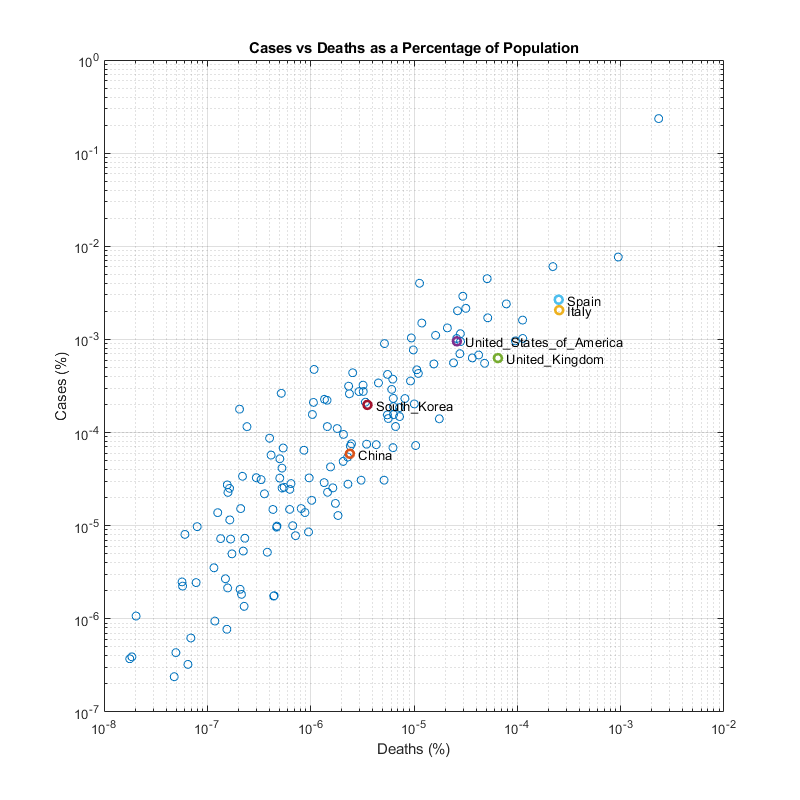


x = by_country.total_deaths ./ by_country.population;
y = by_country.total_cases ./ by_country.population;
fig = figure; ax = axes;
loglog(ax,x,y,'o');
ax.NextPlot = "add";

for id = categorical(highlight')
    country = by_country(by_country.name == id,:);
    xi = country.total_deaths / country.population;
    yi = country.total_cases / country.population;
    loglog(ax,xi,yi,'o','LineWidth',2);
    text(ax,xi*1.2,yi,strrep(char(id),'_','\_'));
end
ylabel('Cases (%)'); xlabel('Deaths (%)')
title( "Cases vs Deaths as a Percentage of Population" )
grid on; fig.Position([3,4]) = [800,800];

T = table( by_country.name, x, y, 'VariableNames', {'name' 'deaths_per_capita' 'cases_per_capita'} );
disp(T(1:10,:))

              name              deaths_per_capita    cases_per_capita
    ________________________    _________________    ________________

    Italy                          0.00025421            0.0020624   
    Spain                          0.00025135            0.0026696   
    United_States_of_America       2.5984e-05           0.00095436   
    France                         0.00011286            0.0010242   
    United_Kingdom                 6.4868e-05           0.00063022   
    Iran                             4.22e-05           0.00068145   
    China                          2.3931e-06            5.929e-05   
    Netherlands                    9.5816e-05           0.00096495   
    Germany                        1.6183e-05            0.0011059   
    Belgium                        0.00011233            0.0016136   



### View Doubling Frequency

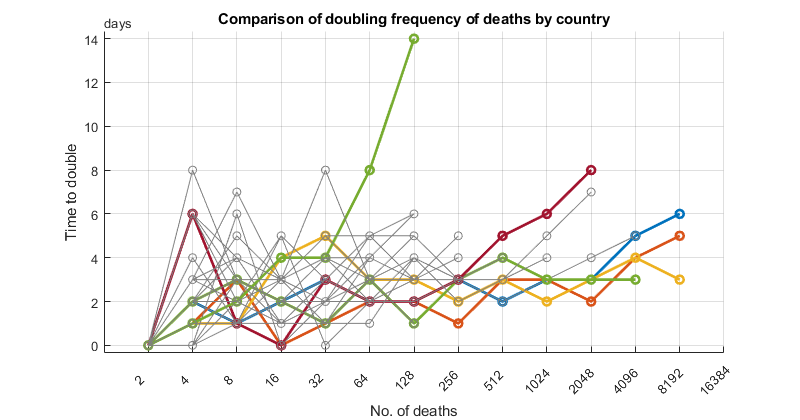

i = 1; n = 2;
N = 30;
freq_double_deaths = table;
freq_double_cases = table;
warning off
while any(by_country.total_cases > n)
    freq_double_deaths.i(i) = i;
    freq_double_deaths.n(i) = n;
    
    freq_double_cases.i(i) = i;
    freq_double_cases.n(i) = n;
    
    for id = by_country.name(1:N)'
        daily = by_date(by_date.location == id,:);
        daily = sortrows(daily,'date','ascend');        
        c = daily.date(find(daily.total_cases>=n,1));        
        d = daily.date(find(daily.total_deaths>=n,1));
        
        if isempty(c); c = NaT; end
        if isempty(d); d = NaT; end
        freq_double_deaths.(string(id))(i) = d;
        freq_double_cases.(string(id))(i) = c;
    end
    n = n * 2;
    i = i + 1;
end
warning on


fig = figure;
ax = axes("NextPlot","add");
x = freq_double_deaths.i;
for id = by_country.name(1:N)'
    d = freq_double_deaths.(string(id));
    y = [days(0);days(diff(d))];
    
     
    if any(id == highlight)
        plot(ax, x, y, '-o' ,'LineWidth', 2)
        text(ax, max(x), max(y), strrep(string(id), '_', '\_'))
    else
        plot(ax, x, y,  '-o', 'Color', [0.5 0.5 0.5])
    end
    
end

xlabel(ax,'No. of deaths')
ylabel(ax,'Time to double')
ax.XTick = freq_double_deaths.i;
ax.XTickLabel = freq_double_deaths.n;
ax.XTickLabelRotation = 45;
title('Comparison of doubling frequency of deaths by country')
grid on
fig.Position(3) = 800;

### View Relative Deaths to Cases

Indicates reach of testing

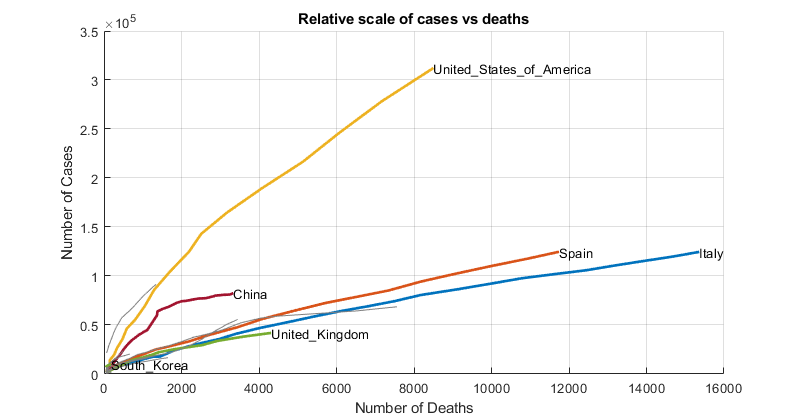

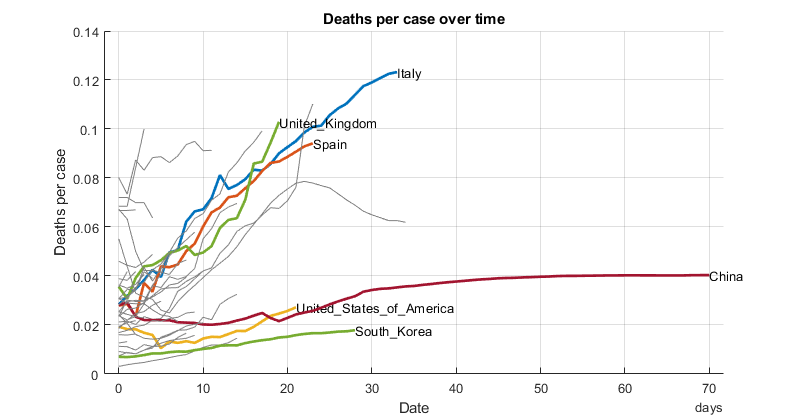

fig = figure;
fig.Position(3) = 800;
ax1 = axes;
ax1.NextPlot = "add";
grid on
xlabel(ax1,"Number of Deaths")
ylabel(ax1,"Number of Cases")
title( "Relative scale of cases vs deaths" )

fig = figure;
fig.Position(3) = 800;
ax2 = axes;
ax2.NextPlot = "add";
grid on
xlabel(ax2,"Date")
ylabel(ax2,"Deaths per case")
title( "Deaths per case over time" )

for id = by_country.name'
    % Get single country summary
    country = by_country(by_country.name == id,:);
    
    % Index relevant data from main table
    ix = by_date.location == id & by_date.date >= country.date_deaths_N;
    
    % Skip country if no relevant rows
    if ~any(ix); continue; end
    
    % Calculate relative dates
    dt = by_date.date(ix) - country.date_deaths_N;
    
    x = by_date.total_deaths(ix);
    y = by_date.total_cases(ix);
    deaths_per_case = x./y;
    
    ax = ax1;
    if any(id == highlight)
        plot(ax, x, y, 'LineWidth', 2)
        text(ax, max(x), max(y), strrep(char(id), '_', '\_'))
    else
        plot(ax, x, y, 'Color', [0.5 0.5 0.5])
    end
    
    ax = ax2;
    x = dt;
    y = deaths_per_case;
    if any(id == highlight)
        plot(ax, x, y, 'LineWidth', 2)
        text(ax, max(x), max(y), strrep(char(id), '_', '\_'))
    else
        plot(ax, x, y, 'Color', [0.5 0.5 0.5])
    end
    xtickformat(ax2,'d')
    
end

### UK Specific Data

country = by_country(by_country.name == "United_Kingdom",:);
disp(country)

         name         geo_id    population        data        total_deaths    total_cases    latest_results    date_deaths_N
    ______________    ______    __________    ____________    ____________    ___________    ______________    _____________

    United_Kingdom    {'UK'}    6.6489e+07    [1×1 struct]        4313           41903         05/04/2020       17-Mar-2020 



daily = by_date(by_date.location == "United_Kingdom",:);
ix = daily.date >= country.date_deaths_N;
daily = daily(ix,:);
latest_date = max(daily.date)

latest_date = datetime
   05/04/2020


delta_death_growth_ratio = daily.deaths ./ (daily.total_deaths - daily.deaths);
delta_case_growth_ratio = daily.cases ./ (daily.total_cases - daily.cases);


### Plot Daily Deaths & Cases

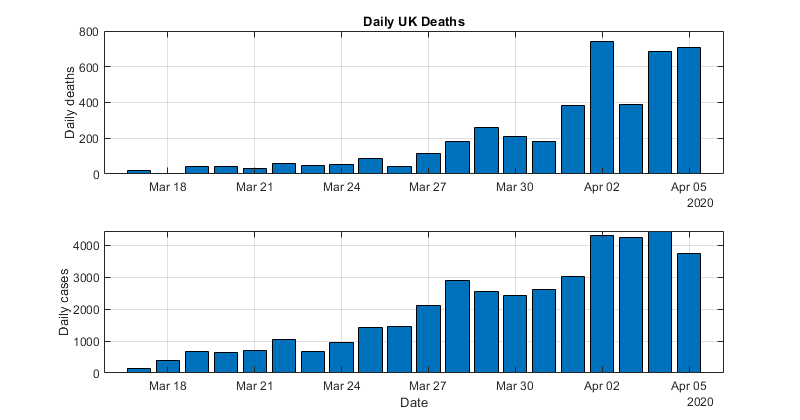

fig = figure;
fig.Position(3) = 800;
ax = subplot(2,1,1); bar( ax, daily.date, daily.deaths );
grid on;
ylabel('Daily deaths');
title("Daily UK Deaths")
ax = subplot(2,1,2); bar( ax, daily.date, daily.cases );
grid on;
ylabel('Daily cases');
xlabel('Date');

### Plot Daily Growth Rate

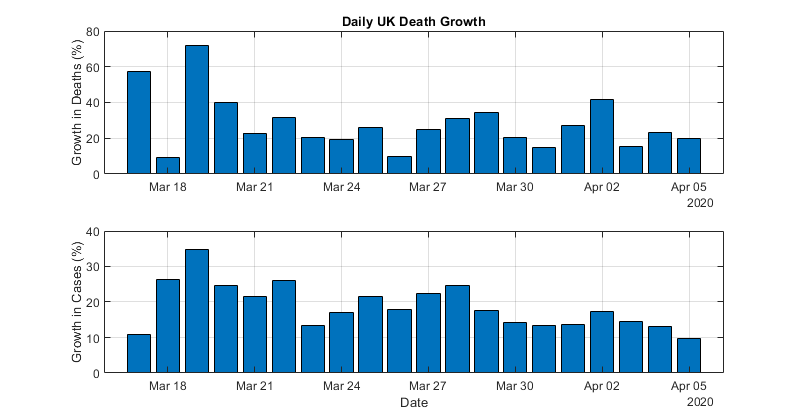

fig = figure;
fig.Position(3) = 800;
ax = subplot(2,1,1); bar( ax, daily.date, delta_death_growth_ratio * 100 );
grid on;
ylabel('Growth in Deaths (%)');
title("Daily UK Death Growth")
ax = subplot(2,1,2); bar( ax, daily.date, delta_case_growth_ratio * 100);
grid on;
ylabel('Growth in Cases (%)');
xlabel('Date');

### Plot Doubling Frequency

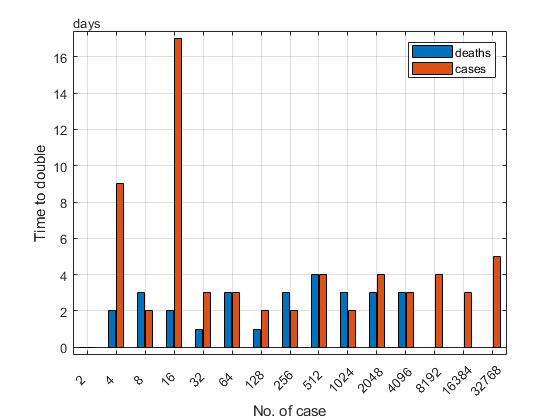

daily = by_date(by_date.location == "United_Kingdom",:);
daily = sortrows(daily,'date','ascend');

i = 1; n = 2;
freq_double = table;
while any(daily.total_cases > n)
    c = daily.date(find(daily.total_cases>=n,1));
    d = daily.date(find(daily.total_deaths>=n,1));
    if isempty(d); d = NaT; end
    freq_double(end+1,["i", "n","deaths","cases"]) = {i n d c};
    n = n * 2;
    i = i + 1;
end

freq_double.period_deaths = [days(0);days(diff(freq_double.deaths))];
freq_double.period_cases = [days(0);days(diff(freq_double.cases))];

figure
ax = axes;
bar(ax,[freq_double.i],[freq_double.period_deaths freq_double.period_cases]');

xlabel(ax,'No. of case')
ylabel(ax,'Time to double')
ax.XTickLabel = freq_double.n;
ax.XTickLabelRotation = 45;
legend(categorical(["deaths","cases"]))
grid on

function dt = findExeedanceDate( dates, value, threshold )
[dates,ix] = sort(dates,'ascend');
value = value(ix);

ix = value >= threshold;
if any(ix)
    dt = dates( find(ix,1) );
else
    dt = NaT;
end
end

function country_data = getCountryData( geo_id )
url = "http://api.worldbank.org/v2/country";
geo_id = lower(geo_id);
switch geo_id
    case 'uk'
        geo_id = 'gb';
end
url = strjoin([url,geo_id],'/' );
data = webread( url, 'format', 'json' );
country_data = data{2};
end
